clearvars;

load 'chirp_80.mat';
load 'bandpass.mat';

Plot the noisy EEG and it's power spectral density

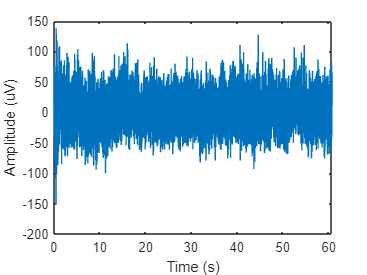

len = length(data)/2;

sampling_rate = 10000;
total_duration_seconds = len / sampling_rate;
time_axis = 0:1/sampling_rate:total_duration_seconds-(1/sampling_rate);

figure;
% plot(data(1:len));
% hold on;
plot(time_axis,(data(len+1:end)/10^(-6)));
xlabel("Time (s)");
ylabel("Amplitude (uV)");

Initializing Window Designer....

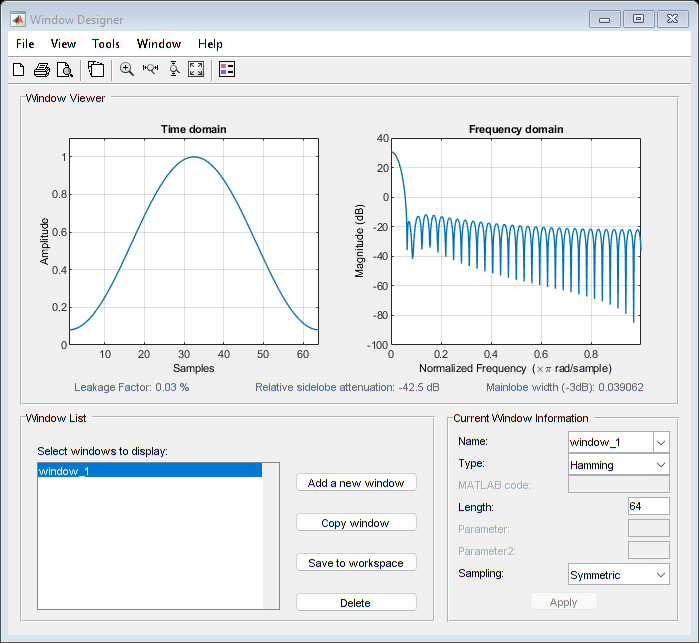

. done. 



nfft = len;
[pxx_noisyEEG,f_noisyEEG] = periodogram(data(len+1:end),window,nfft,sampling_rate);

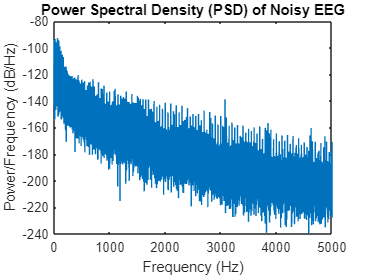


figure;
plot(f_noisyEEG, 10*log10(pxx_noisyEEG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of Noisy EEG');

Applying bandwidth of 100-3000 hz

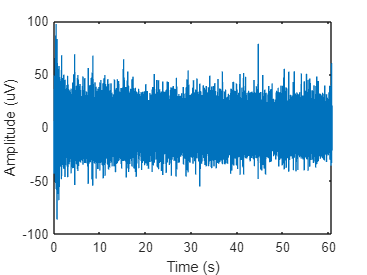

filtered_signal = filtfilt(bandpass,1, data(len+1:end));
figure;
% plot(data(1:len));
% hold on;
plot(time_axis,filtered_signal/(10^-6));
xlabel("Time (s)");
ylabel("Amplitude (uV)");

Initializing Window Designer....

. done. 



[pxx_filtEEG,f_filtEEG] = periodogram(filtered_signal,window,nfft,sampling_rate);

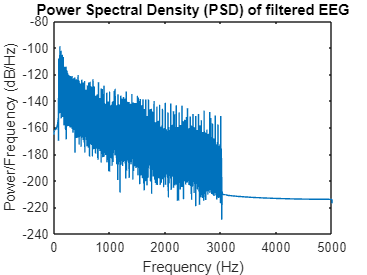


figure;
plot(f_filtEEG, 10*log10(pxx_filtEEG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of filtered EEG');